# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 전유진**

**학번**** : 201911694**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1];
N = 4;
Xk = fft(x,N)

Xk =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 + 0.0000i  -1.0000 + 1.0000i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x = [1,2,2,1, zeros(1,12)];
N = 16;
Xk = fft(x,N)

Xk =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

x1 = [4,1,-1,1];
N1 = 4;
X1 = fft(x1,N1)

X1 =      5     5     1     5


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

x2 = [1,0,-1,-1,0];
N2 = 5;
X2 = fft(x2,N2)

X2 =    -1.0000    2.6180    0.3820    0.3820    2.6180


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

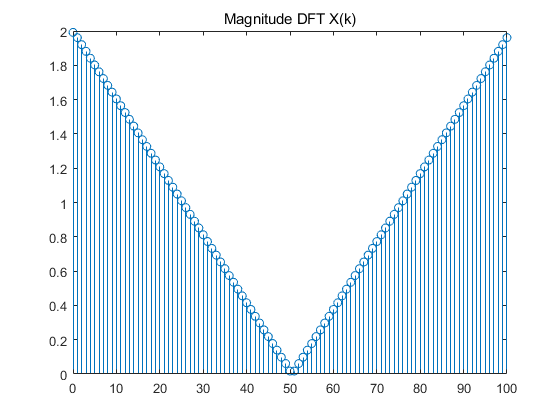

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
k = 0:N-1;

Xk = fft(xn,N);
magXk = abs(Xk);
phaXk = angle(Xk)*180/pi;


stem(k, magXk);
title('Magnitude DFT X(k)');

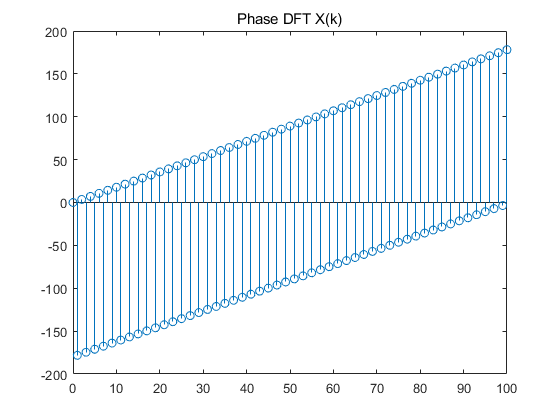

stem(k, phaXk);
title('Phase DFT X(k)');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

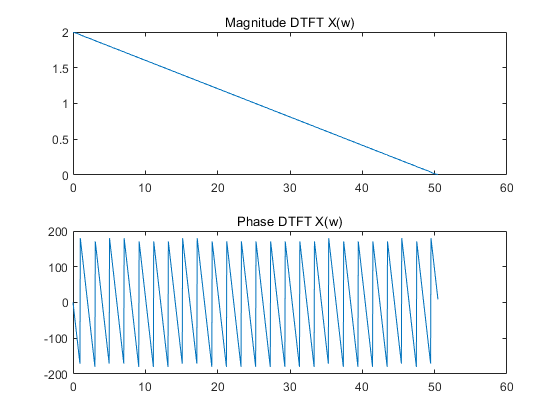

[X,w] = freqz(xn,1,1000);
magXk = abs(X);
phaXk = angle(X)*180/pi;
Dw = (2*pi)/N;

subplot(2,1,1);
plot(w/Dw, magXk);
title('Magnitude DTFT X(w)');
subplot(2,1,2);
plot(w/Dw, phaXk);
title('Phase DTFT X(w)');

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

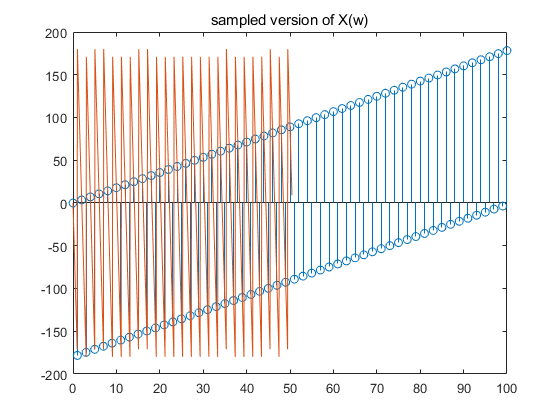

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
k = 0:N-1;

Xk = fft(xn,N);
magXk2 = abs(Xk);
phaXk2 = angle(Xk)*180/pi;

[X,w] = freqz(xn,1,1000);
magXk3 = abs(X);
phaXk3 = angle(X)*180/pi;
Dw = (2*pi)/N;

subplot(1,1,1);
stem(k, phaXk2); hold on;
plot(w/Dw, phaXk3); hold off;
title('sampled version of X(w)');

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.